## Genetic Algorithm Optimization for the Generator

gamultiobj stopped because the average change in the spread of Pareto solutions is less than options.FunctionTolerance.


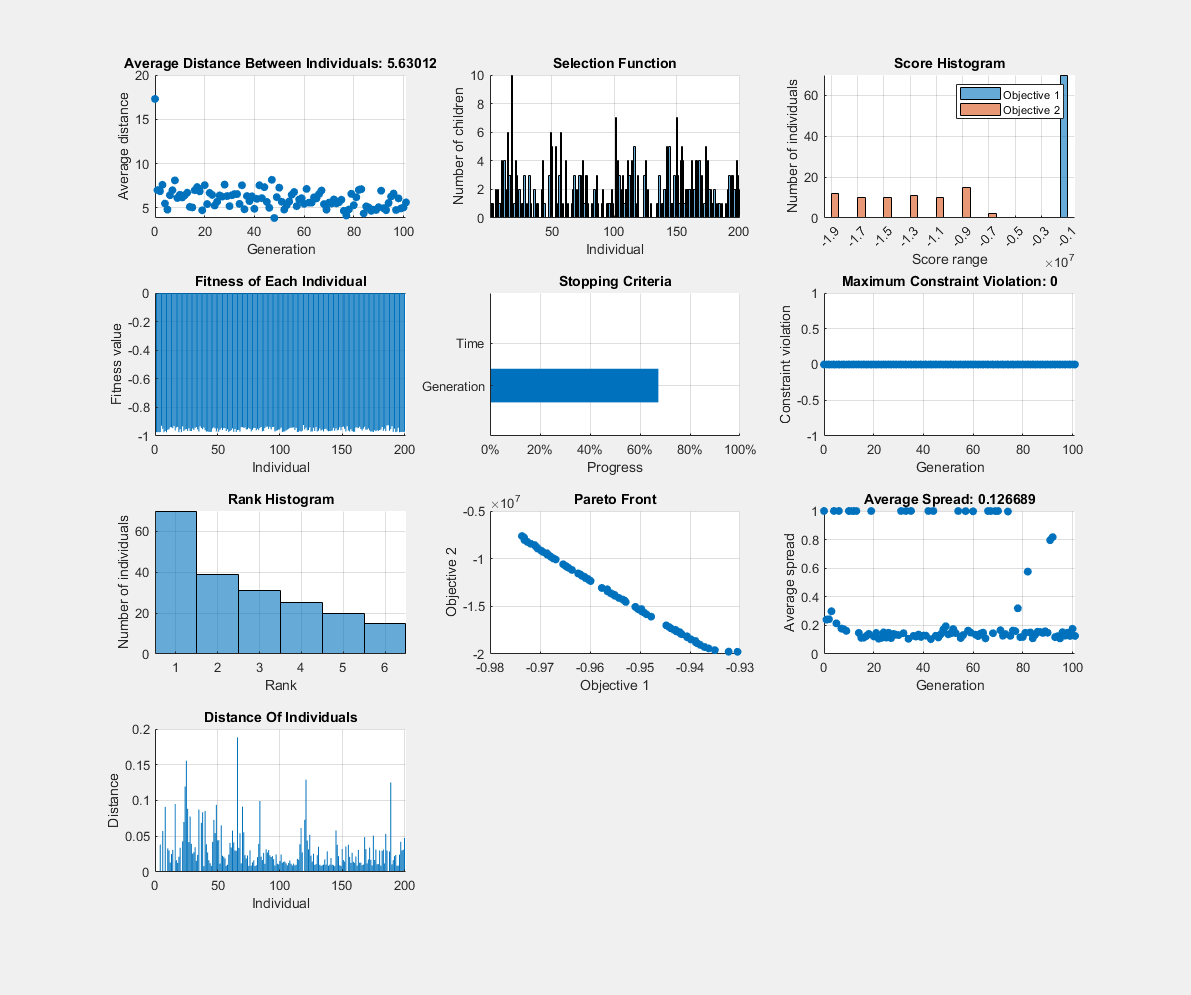

% Set nondefault solver options
options = optimoptions("gamultiobj","PopulationSize",200,"MaxGenerations",...
    150,"UseParallel",true,"ConstraintTolerance",0.1,"FunctionTolerance",0.1,...
    "PlotFcn",["gaplotdistance","gaplotselection","gaplotscorediversity",...
    "gaplotscores","gaplotstopping","gaplotmaxconstr","gaplotrankhist",...
    "gaplotpareto","gaplotspread","gaplotparetodistance"]);

% Solve
[solution,objectiveValue] = gamultiobj(@optimization_cost,number_of_inputs,...
    [],[],[],[],lower_bounds,upper_bounds,[],IntCon,options);


% Clear variables
clearvars options